x=0:0.1:3;
size(x);

y=[sin(x); cos(x)] + randn(2,31);
%binned_plot(x,y)

t_int = open('matlab2.mat');
t_int = t_int.t_int_temp;

mat = open('matlab.mat');
mat = mat.mat;
mat(mat>50) = nan;

rCount = size(mat,1);

a=1;
b=2;


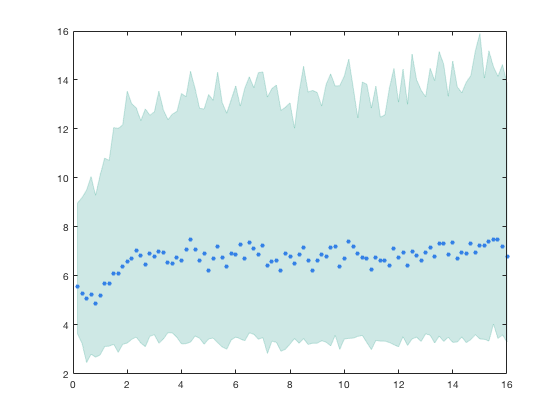

%function [x_med_out,y_med,y_low,y_high] = binned_plot(x,y,varargin)
%   BINNED_PLOT binned scatter plot
%
%   BINNED_PLOT(X,Y) splits vector X into bins of aproximately equal size,
%   and plots each median against the median of the corresponding Y-values,
%   as well as their inter-quartile range. X and Y must have the same
%   number of rows or columns.
%
%   BINNED_PLOT(X,Y,NUM_BINS) also specifies the (maximum) number of bins.
%
%
%   [X_MED,Y_MED,Y_LOW,Y_HIGH] = BINNED_PLOT(...) returns the median of the
%    X-bin, the median, lower and upper quartile of the corresponding Y-values
%
%   Additional properties can be set as attribute-value pairs:
%   - 'y_range'         : specifies the width of the Y-band (range 0 .. 0.5;
%                         e.g., 0.5 plots the range between maxima and minima);
%                         default: 0.25
%   - 'y_mean_std'      : plot means and standard deviations instead of medians
%                         and quartiles ['on','off']
%   - 'style'           : plotting style (same options as in plot command)
%   - 'density'         : transparency corresponds to the number of points in
%                         the shaded area ['on','off']
%   - 'transparency'    : transparency of filled range (for non-density plots)
%   - 'transparency_min': minimum transparency of filled range (for density plots)
%   - 'transparency_max': maximum transparency of filled range (for density plots)
%
%
%   Example:
%   x=0:0.1:20;
%   y=[sin(x); cos(x)] + randn(2,201);
%   binned_plot(x,y)
%

%   Stefan Schroedl
%   04/07/2008



% optargin = size(varargin,2);
% stdargin = nargin - optargin;
% 
% if (stdargin<2)
%     error('at least two arguments required')
% end


% defaults for optional arguments
num_bins             = [];
y_range              = [];
style                = [];
y_mean_std           = 0;
transparency         = 0.1;
transparency_max     = 0.6;
transparency_min     = 0.1;
density_transparency = 0;

% parse optional arguments
i=1;
optargin = 0;
while (i <= optargin)
    if (i==1 && isnumeric(varargin{i}))
        num_bins = varargin{i}; % interpret as number of bins
        i = i + 1;
    elseif (strcmp(varargin{i},'style') && i < optargin)
        style = varargin{i+1};
        i = i + 2;
    elseif (strcmp(varargin{i},'y_range') && i < optargin)
        y_range = varargin{i+1};
        i = i + 2;
    elseif (strcmp(varargin{i},'transparency') && i < optargin)
        transparency = varargin{i+1};
        i = i + 2;
    elseif (strcmp(varargin{i},'transparency_max') && i < optargin)
        transparency_max = varargin{i+1};
        i = i + 2;
    elseif (strcmp(varargin{i},'transparency_min') && i < optargin)
        transparency_min = varargin{i+1};
        i = i + 2;
    elseif (strcmp(varargin{i},'y_mean_std') && i < optargin)
        if (strcmp(varargin{i+1},'on'))
            y_mean_std = 1;
        elseif (strcmp(varargin{i+1},'off'))
            y_mean_std = 0;
        else
            error('unrecognized option for y_mean_std, should be [on/off]');
        end
        i =  i + 2;
    elseif (strcmp(varargin{i},'density') && i < optargin)
        if (strcmp(varargin{i+1},'on'))
            density_transparency = 1;
        elseif (strcmp(varargin{i+1},'off'))
            density_transparency = 0;
        else
            error('unrecognized option for density, should be [on/off]');
        end
        i =  i + 2;
    elseif (ischar(varargin{i}))
        error('unrecognized attribute: %s', varargin{i});
    else
        error('at most three arguments expected');
    end
end

if (transparency_min >= transparency_max)
    error('transparency_min should be smaller than transparency_max');
end

% determine input matrix sizes
[nx,mx] = size(x);
[ny,my] = size(y);

if nx > 1 && mx > 1
    error('first argument must be a vector');
end

% adjust matrices to be column vectors

if mx>1
    % transpose
    x = x(:);
    nx = mx;
    mx = 1;
end

if my == nx
    % transpose
    y = y';
    [ny,my] = size(y);
else
    if ny ~= nx
        error('first and second arguments must have either same number of rows or columns');
    end
end


if isempty(num_bins)
    num_bins = max( min(length(x),3), floor(sqrt(length(x)-1))-1); % default heuristic for number of bins
else if ~isnumeric(num_bins)
        db        error('third argument num_bins must be numeric');
    end
end

if isempty(y_range)
    y_range = 0.25; % default: quartile
end

if isempty(style)
    style = ''; % no style specified
end

% determine colors and markers
colors  = repmat('b',1,my);
noColSpec = cell(1,my);
for i=1:my
    [colors(i),noColSpec{i}]  = getColorSpec(style,i);
end

% x quantiles
qvals = 0:(1/num_bins):(1-1/num_bins);
x_quant = quantile(x,[qvals 1]);

% remove identical bins
x_quant = sort(unique(x_quant));

% due to interpolation, some bins can still be empty
x_quant2 = x_quant;
x_quant = x_quant(1);
count_bin = length(find(x>x_quant2(1)));
for i=2:length(x_quant2)
    count_bin2 = length(find(x>x_quant2(i)));
    if count_bin2 ~= count_bin
        x_quant = [x_quant x_quant2(i)];
    end
    count_bin = count_bin2;
end

% preallocate outputs
x_med = zeros(length(x_quant)-1,1);
y_med = zeros(length(x_quant)-1,my);
y_low  = zeros(length(x_quant)-1,my);
y_high = zeros(length(x_quant)-1,my);

% desired y range

for i = 1:length(x_quant)-1
    idx = x >= x_quant(i) & (x < x_quant(i+1));
    if (~y_mean_std)
        
        q = quantile(y(idx,:),[0.5-y_range 0.5 0.5 + y_range]);
        % hack for quantile output dim
        if my == 1
            q = q';
        end
        y_low(i,:)  = q(1,:);
        y_med(i,:)  = q(2,:);
        y_high(i,:) = q(3,:);
        x_med(i)    = median(x(idx));
    else
        % use mean and std dev
        m = mean(y(idx,:));
        s = std(y(idx,:));
        y_med(i,:)  = m;
        y_low(i,:)  = m-s;
        y_high(i,:) = m+s;
        x_med(i)    = mean(x(idx));
    end
end

%%if (nargout == 0)
    hold_mode = ishold;
    x_min = x_quant(1);
    x_max  = x_quant(end);
    for i=1:my
        inner_spec = strcat(colors(i), noColSpec{i});
        
        if(~density_transparency)
            
            e = 10;
            % fill between quartiles
%             xpoints=[x_min; x_med; x_max; x_max; flipud(x_med); x_min]
%             ypoints=[y_high([ 1 1:end end],i); flipud(y_low([1 1:end end],i)) ]
            
            %xpoints = [1:e,fliplr(1:e)]
            
            xpoints = [t_int;flipud(t_int)];
            y1ps = prctile(mat,25,2);
            y2ps = prctile(mat,75,2);
            ypoints = [y1ps;flipud(y2ps)];
            %ypoints = permute(mat(1:e,b),[2 1]);
            %ypoints = [ypoints,fliplr(arrayfun(@(x) x+10, ypoints))]
            fillhandle=fill(xpoints,ypoints,colors(i));
            set(fillhandle,'EdgeColor',colors(i),'FaceAlpha',transparency,'EdgeAlpha',transparency); %set transparency
        else
            % precompute trapezoids, areas
            xpoints   = zeros(4,length(x_med)+1);
            ypoints   = zeros(4,length(x_med)+1);
            area_fill = zeros(1,length(x_med)+1);
            
            xpoints(:,1) = [x_min; x_med(1); x_med(1); x_min];
            ypoints(:,1) = [y_high(1,i); y_high(1,i); y_low(1,i); y_low(1,i)];
            area_fill(1) = (xpoints(2,1)-xpoints(1,1))*(ypoints(1,1)-ypoints(4,1)+ypoints(2,1)-ypoints(3,1))/2;
            
            for j=1:(length(x_med)-1)
                xpoints(:,j+1) = [x_med(j); x_med(j+1); x_med(j+1); x_med(j)];
                ypoints(:,j+1) = [y_high(j,i); y_high(j+1,i); y_low(j+1,i); y_low(j,i)];
                area_fill(j+1) = (xpoints(2,j+1)-xpoints(1,j+1))*(ypoints(1,j+1)-ypoints(4,j+1)+ypoints(2,j+1)-ypoints(3,j+1))/2;
            end
            
            xpoints(:,end) = [x_med(end); x_max; x_max; x_med(end)];
            ypoints(:,end) = [y_high(end,i); y_high(end,i); y_low(end,i); y_low(end,i)];
            area_fill(end) = (xpoints(2,end)-xpoints(1,end))*(ypoints(1,end)-ypoints(4,end)+ypoints(2,end)-ypoints(3,end))/2;
            
            area_max = max(area_fill);
            area_min = min(area_fill);
            area_range = area_max - area_min;
            if (area_range == 0)
                area_range = 1;
            end
            transparency_range = transparency_max - transparency_min;
            % scale transparency according to density (i.e., inversely
            % proportional to trapezoid area)
            transp_mod = transparency_max - (area_fill - area_min) .* transparency_range ./ area_range;
            for j=1:(length(x_med)+1)
                fillhandle=fill(xpoints(:,j),ypoints(:,j),colors(i),'LineStyle','none');
                hold on;
                set(fillhandle,'EdgeColor',colors(i),'FaceAlpha',transp_mod(j),'EdgeAlpha',transp_mod(j)); % set transparency
            end
        end
        % plot median line
        hold on;
        %plot(x_med,y_med(:,i),inner_spec);
        med = prctile(mat,50,2);
        scatter(t_int,med,20,[.2 .5 .9],'filled');
    end
    
    % restore old hold mode
    if hold_mode == 0
        hold off;
    end

%%else
  %%  x_med_out = x_med;
%%end


% auxiliary function to retrieve color specification (if any)  and remainder

function [color,noColSpec] = getColorSpec(s,i)
colors = 'bgrcmykw';
color=colors(mod(i-1,8) + 1); % default color cycle
noColSpec = '-';              % default line style
if (~isempty(s))
    idx=ismember(s,colors);
    if any(~idx)
        noColSpec=s(~idx);
    end
    if any(idx)
        color=s(idx(1));
    end
end
end
